# Lab 4: Working with 'real' data

## Megan Miyasaki 

Partner: Kuan Lee

## Introduction

In this lab we are going to work on how to estimate the background from 'real' data. Real is in air quotes because the data is actually from simplified simulations to make the problems manageable in a single lab. But the data will have *some* features that resemble that of real data sets.

## Problem 1

In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays.

As with most data, there are 'features.' Your lab instructor has helpfully incorporated the meta-data into your data file.

**1) Down load the data from the course website (gammaray_lab4.h5), and import it into your working environment. The data has 4 columns and more than 25 million rows. The columns are time (in gps seconds), Solar phase (deg) showing the position of the sun relative to the orbit, Earth longitude (deg) giving the position of the spacecraft relative to the ground, and particle counts. Make a few plots, generally exploring your data and making sure you understand it. Give a high level description of the data features you see. Specifically comment on whether you see signal contamination in your data, and how you plan to build a background pdf().**

*Below is code to download that 'real world' data and import it for this report, as well as the plots that are used to explore the data. Since I do not have a known background just data, I want to find signal - free data, and finding the 'shape' of the background. *

clear;close all;clc;

% downloading and importing the data for problem 1:

h5disp("gammaray_lab4.h5"); 

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata=h5read("gammaray_lab4.h5",'/data');
mydata(1,:); 

## Counts as the constant y -axis

*I chose to use the number of counts to be my consistent variables because it seemed to be the best correlation to all of them, using GPS time compared to all the other categorizes and measurements would not have a very consistent patern, same with the other categories. But if we just look at the GPS time, or the solar phase, or the earth phase and see how any couts there were, we have a good correlation and comparison. *

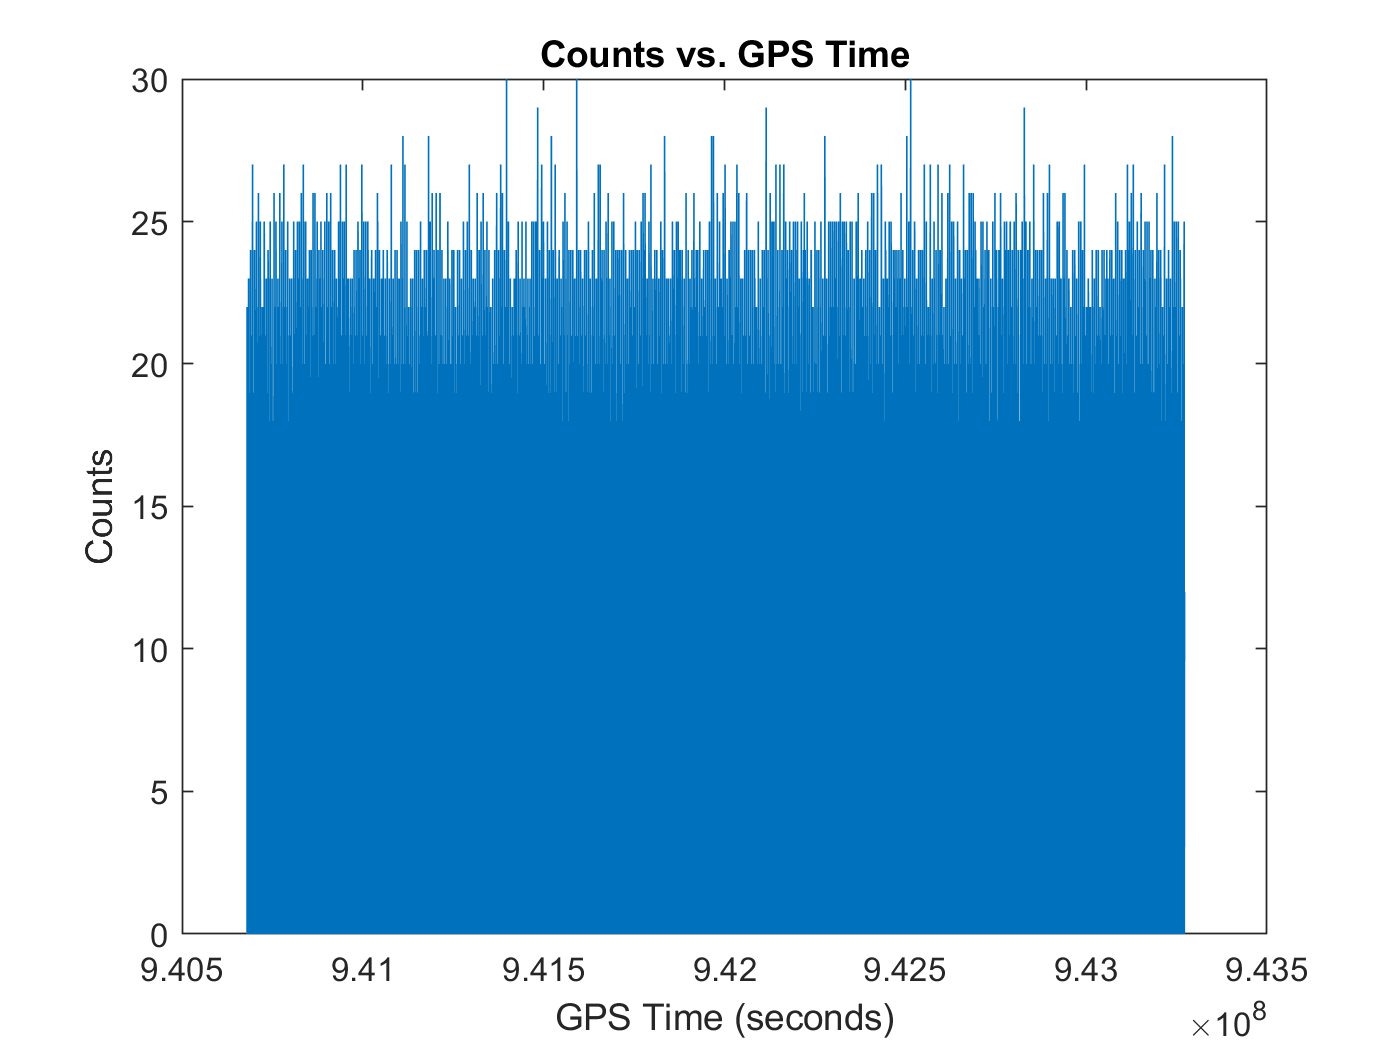

% Counts vs. Time
gps=mydata(:,1); 
counts= mydata(:,4); 
plot (gps,counts)
title('Counts vs. GPS Time')
xlabel('GPS Time (seconds)')
ylabel('Counts')

From this plot I see no patterns emerging. 

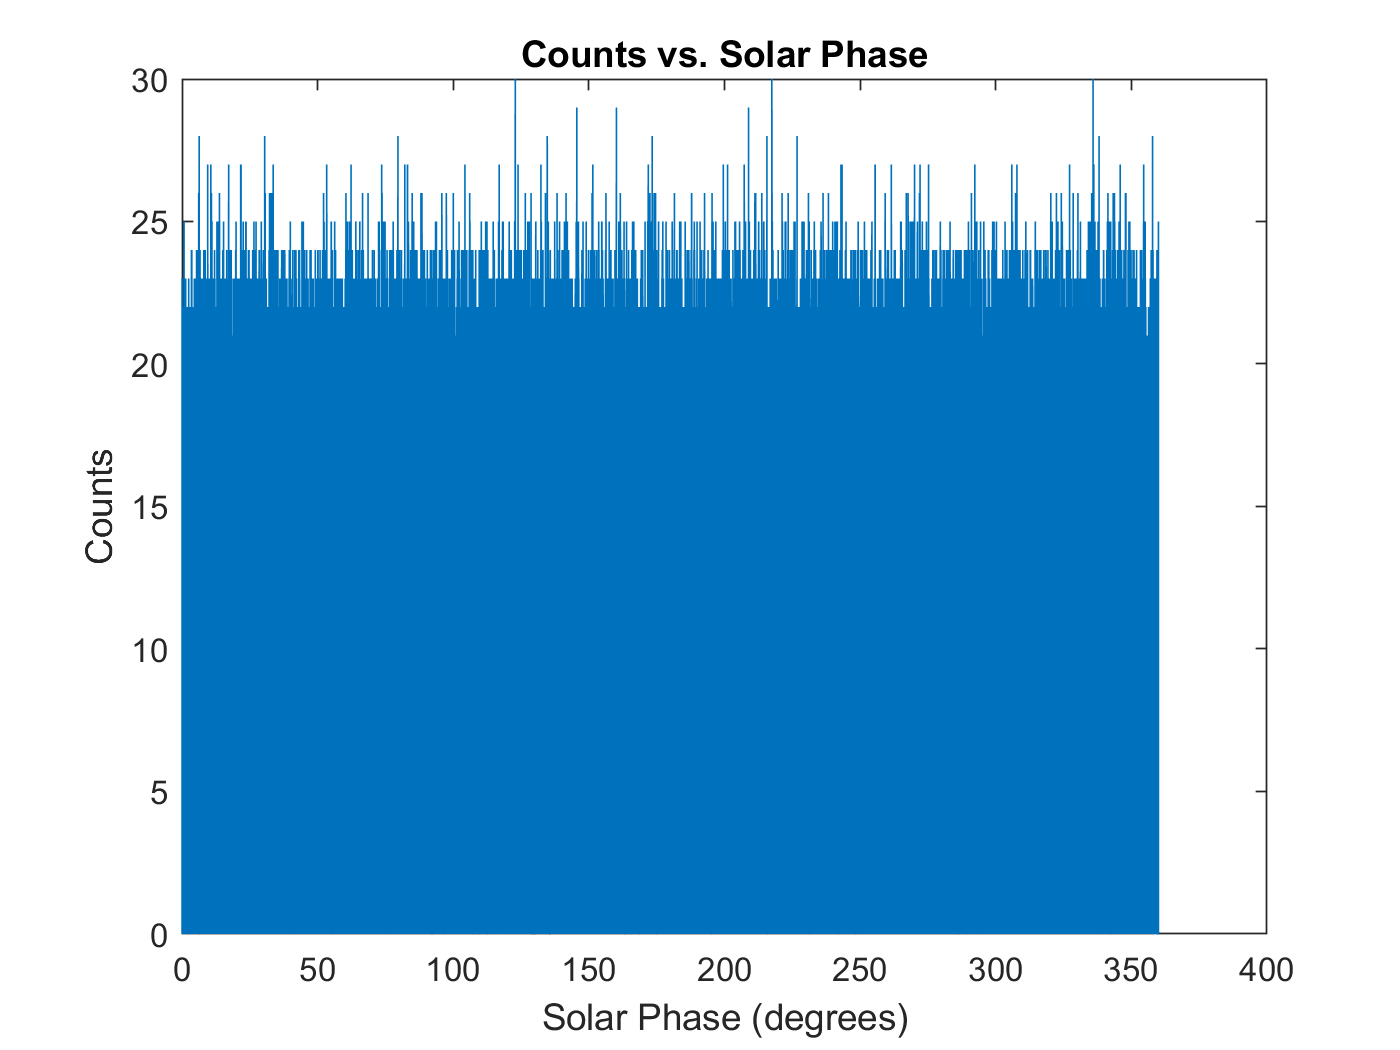

% Counts vs. Solar orbit
solar=mydata(:,2);
plot(solar,counts)
title('Counts vs. Solar Phase')
xlabel('Solar Phase (degrees)')
ylabel('Counts')

Again no pattern and look pretty similar to the count vs. GPS time point. 

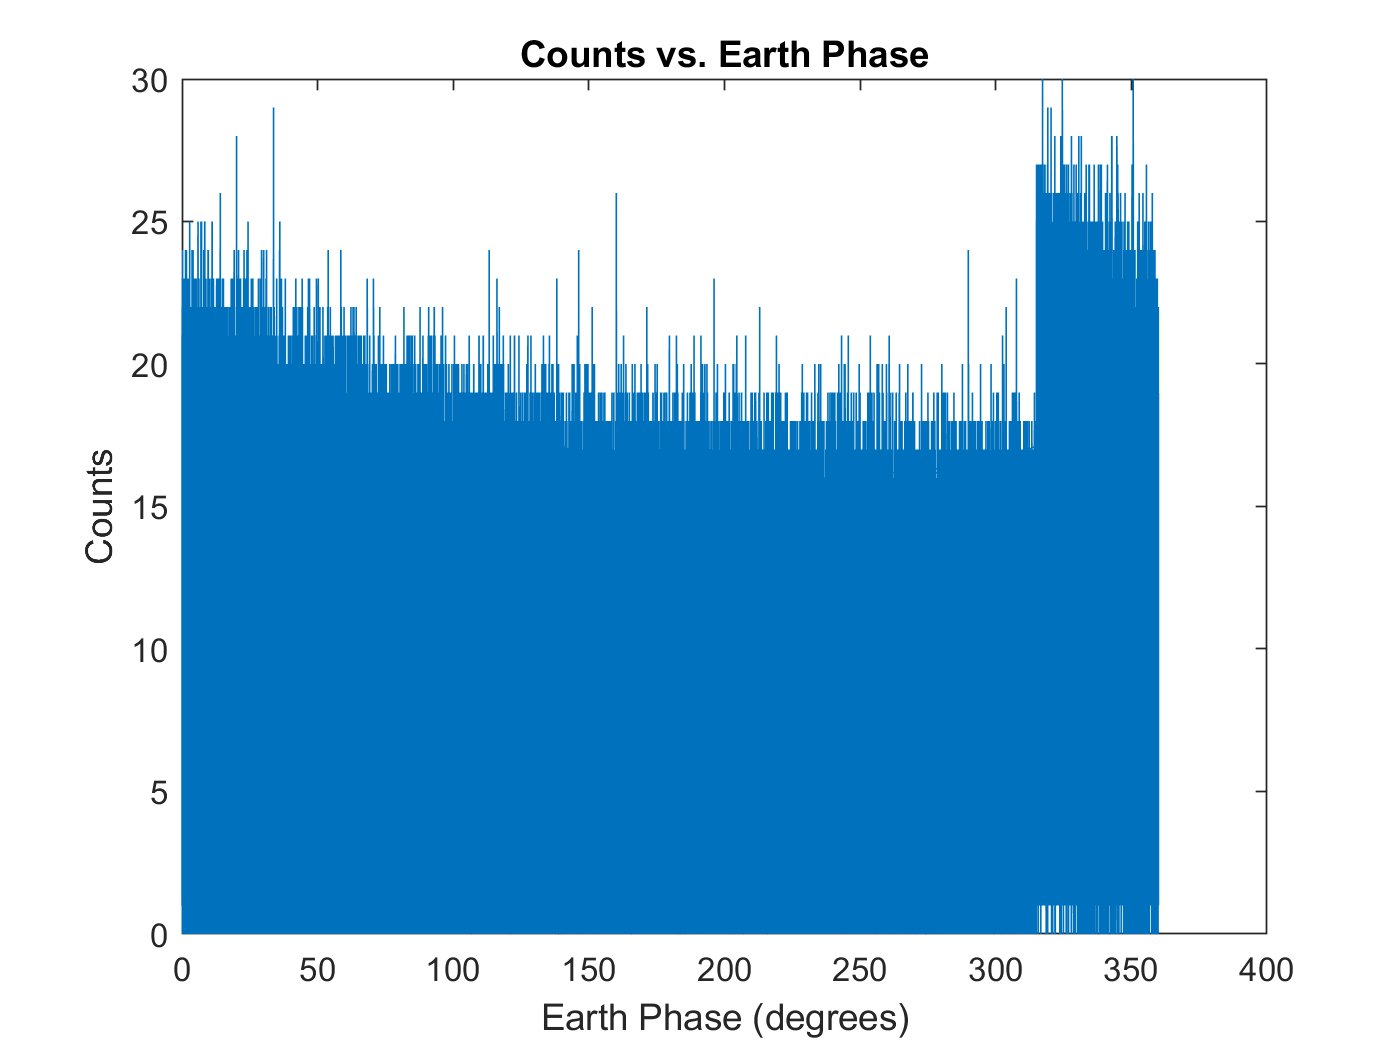

% Counts vs. Earth
earth=mydata(:,3);
plot(earth,counts)
title('Counts vs. Earth Phase')
xlabel('Earth Phase (degrees)')
ylabel('Counts')

This plot is different, there seems to be a space of 'signal free' data, that being the Earth is "blocking" the spacecraft just as some scientist would take images of the inside of the telescope dome to get signal free data. While we do have this knowledge we know that, gamma ray burst can come from everywhere so now we need to sort out the true signal free data from the background cosmic rays. 

## 1st and 2nd time interval of the measurement

*This is to see what is happening in one interval of the measurement, since the time between each data point 0.1 seconds, so the period of the orbit is 90 minutes, therefore 54000 should be the amount of data points you collect in one orbit of the earth. I want to see how the data relates in different time intervals of measurment too see how the distribution acts. *

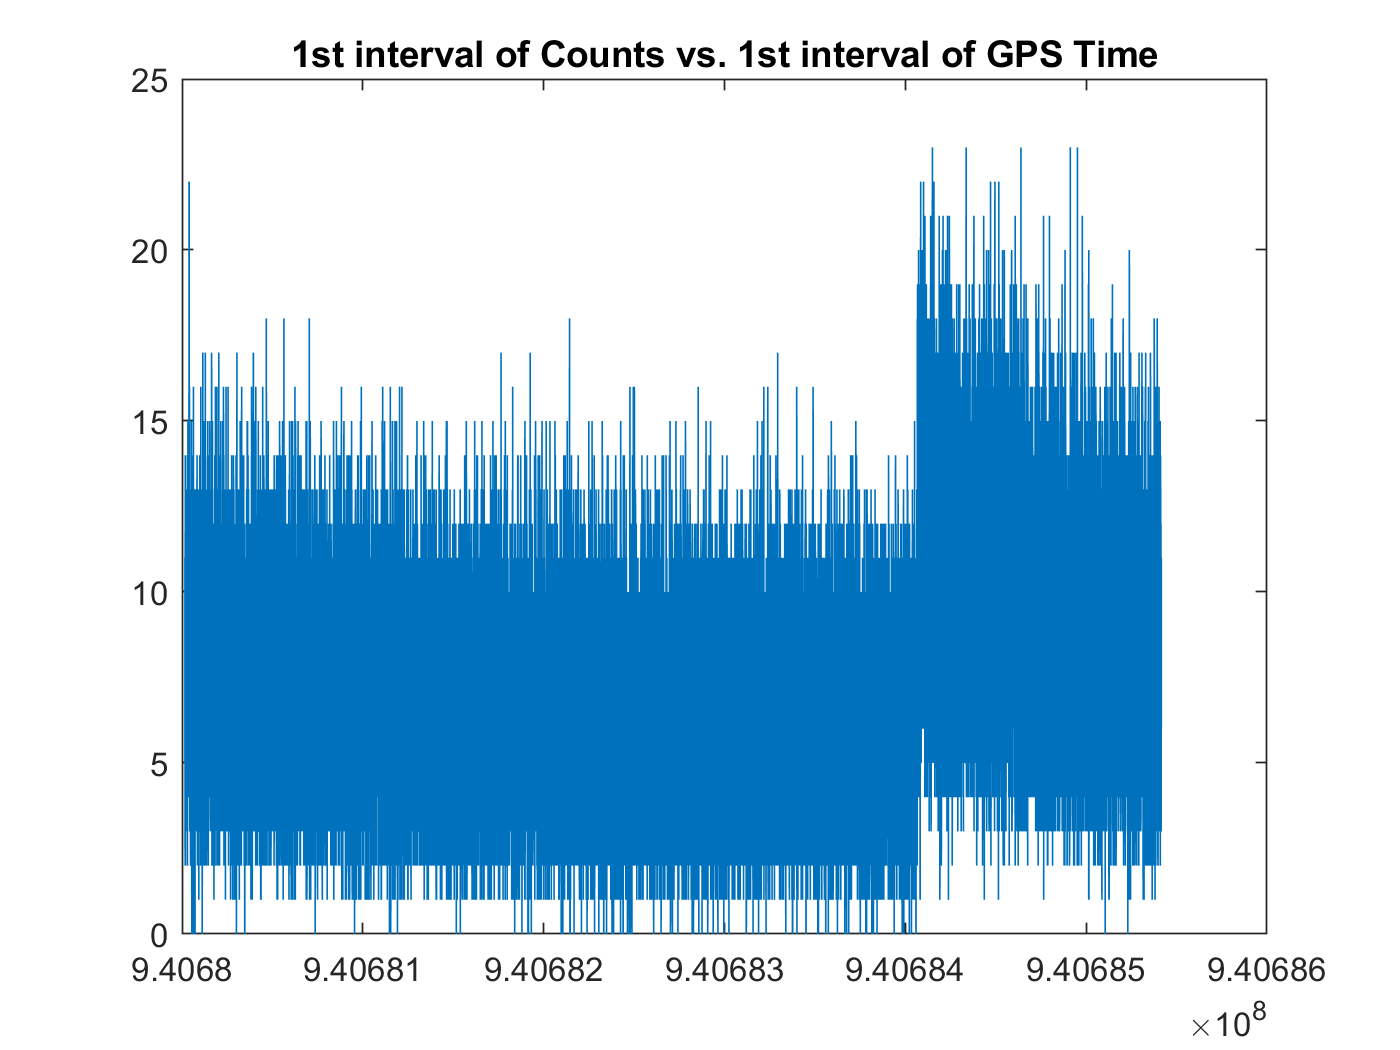

% one interval 
counts1= mydata(1:54000,4);
time1 = mydata(1:54000,1);
solar1 = mydata(1:54000,2);
earth1 = mydata(1:54000,3);

plot(time1,counts1)
title('1st interval of Counts vs. 1st interval of GPS Time')

Possible pattern here as the counts jump back up? I know that the data does not start at the orbit starting at 0 degrees. 

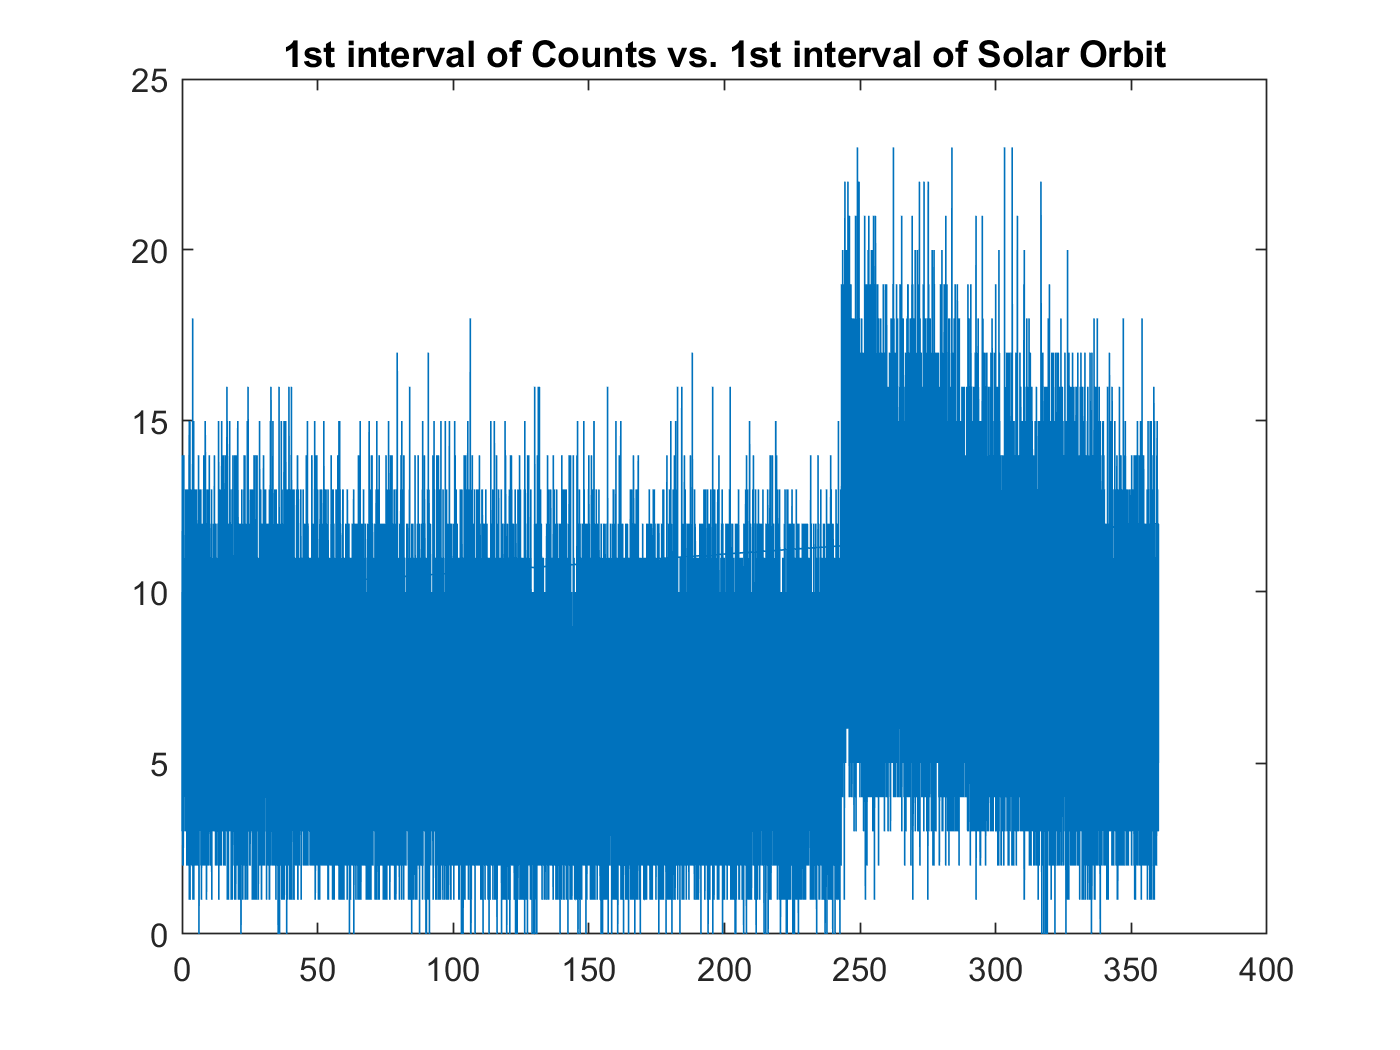

plot(solar1,counts1)
title('1st interval of Counts vs. 1st interval of Solar Orbit')

Another jump in counts, still keeping a look out for this pattern

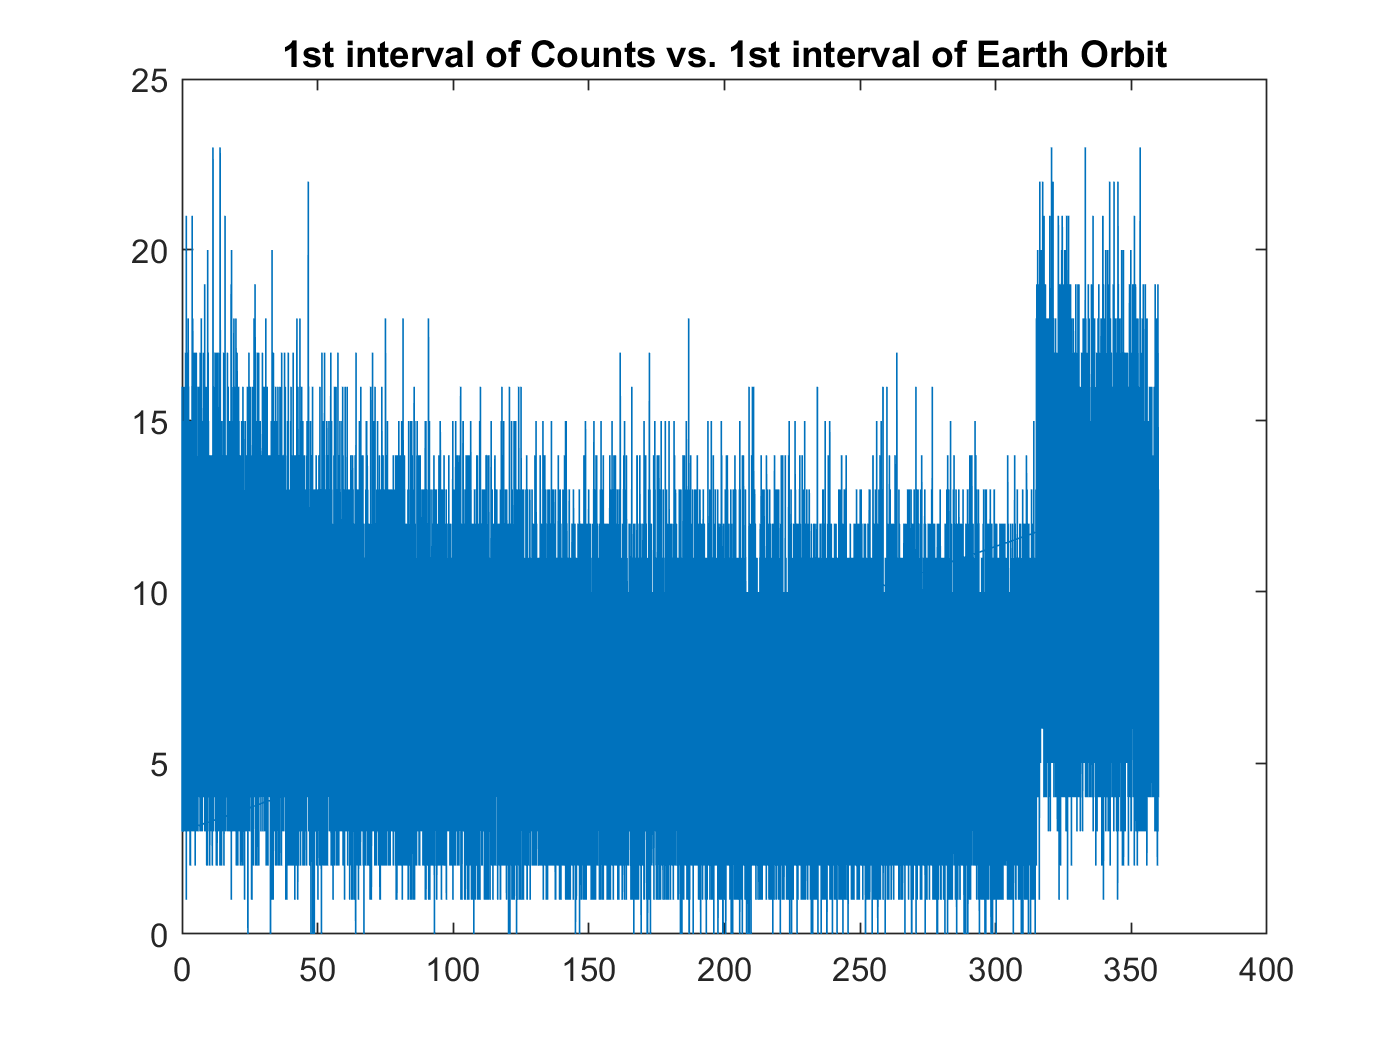

plot(earth1,counts1)
title('1st interval of Counts vs. 1st interval of Earth Orbit')

Same jump, need a second interval to see a true pattern. 

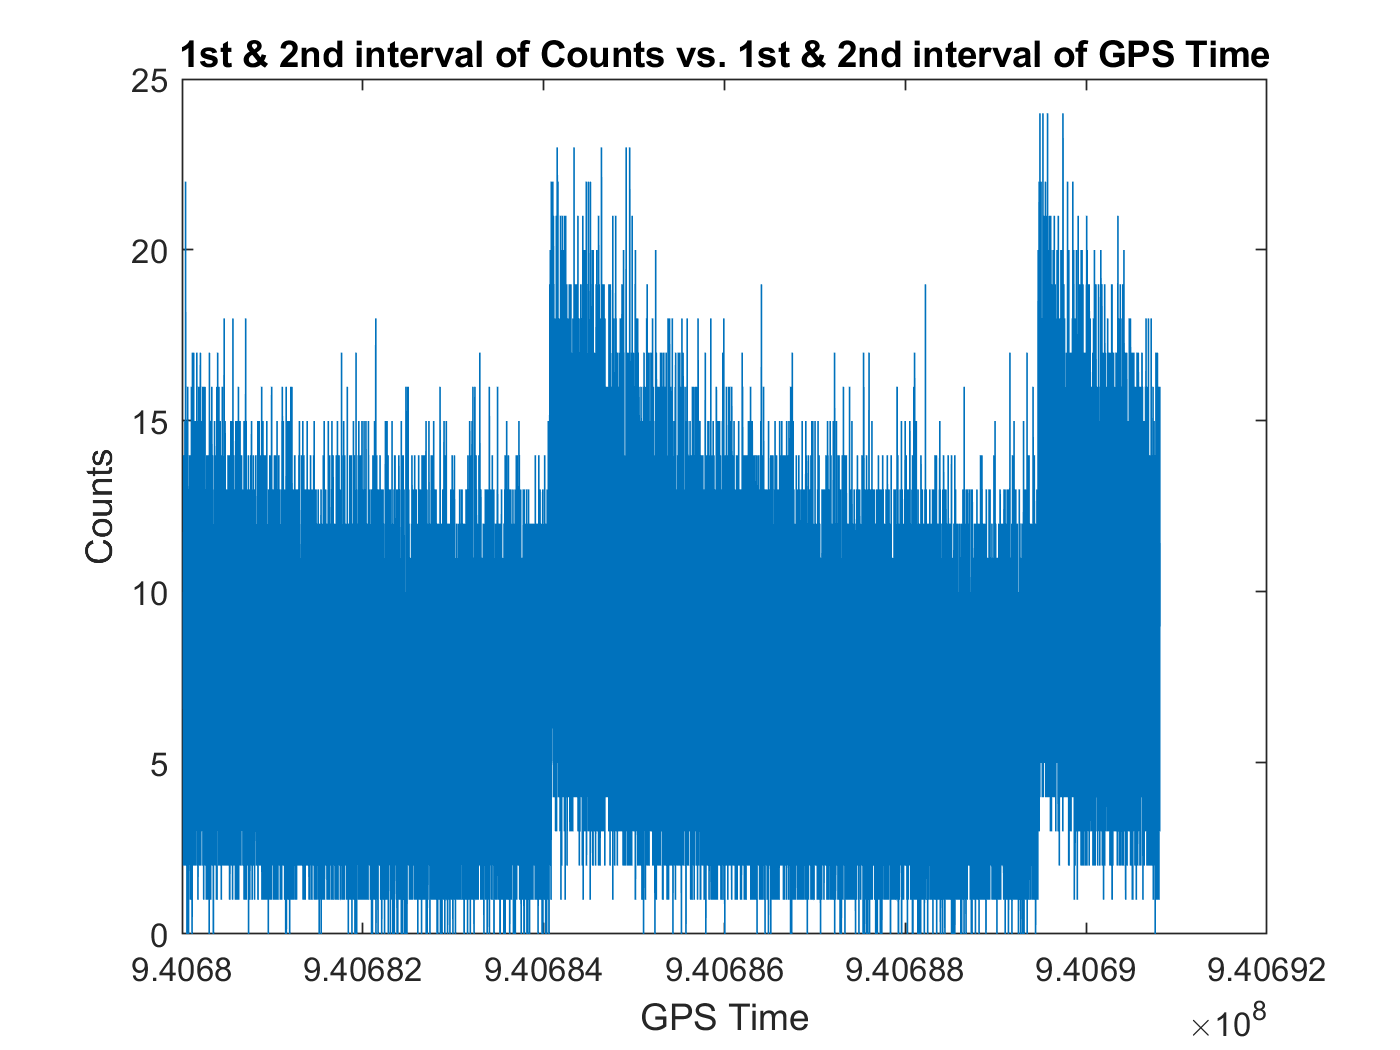

% second interval
counts2= mydata(1:54000*2,4);
time2 = mydata(1:54000*2,1);
solar2 = mydata(1:54000*2,2);
earth2 = mydata(1:54000*2,3);

plot(time2,counts2)
title('1st & 2nd interval of Counts vs. 1st & 2nd interval of GPS Time')
xlabel('GPS Time')
ylabel('Counts')

Seeing a period exponetial decay in the counts as time goes one, making the counts are time dependent. 

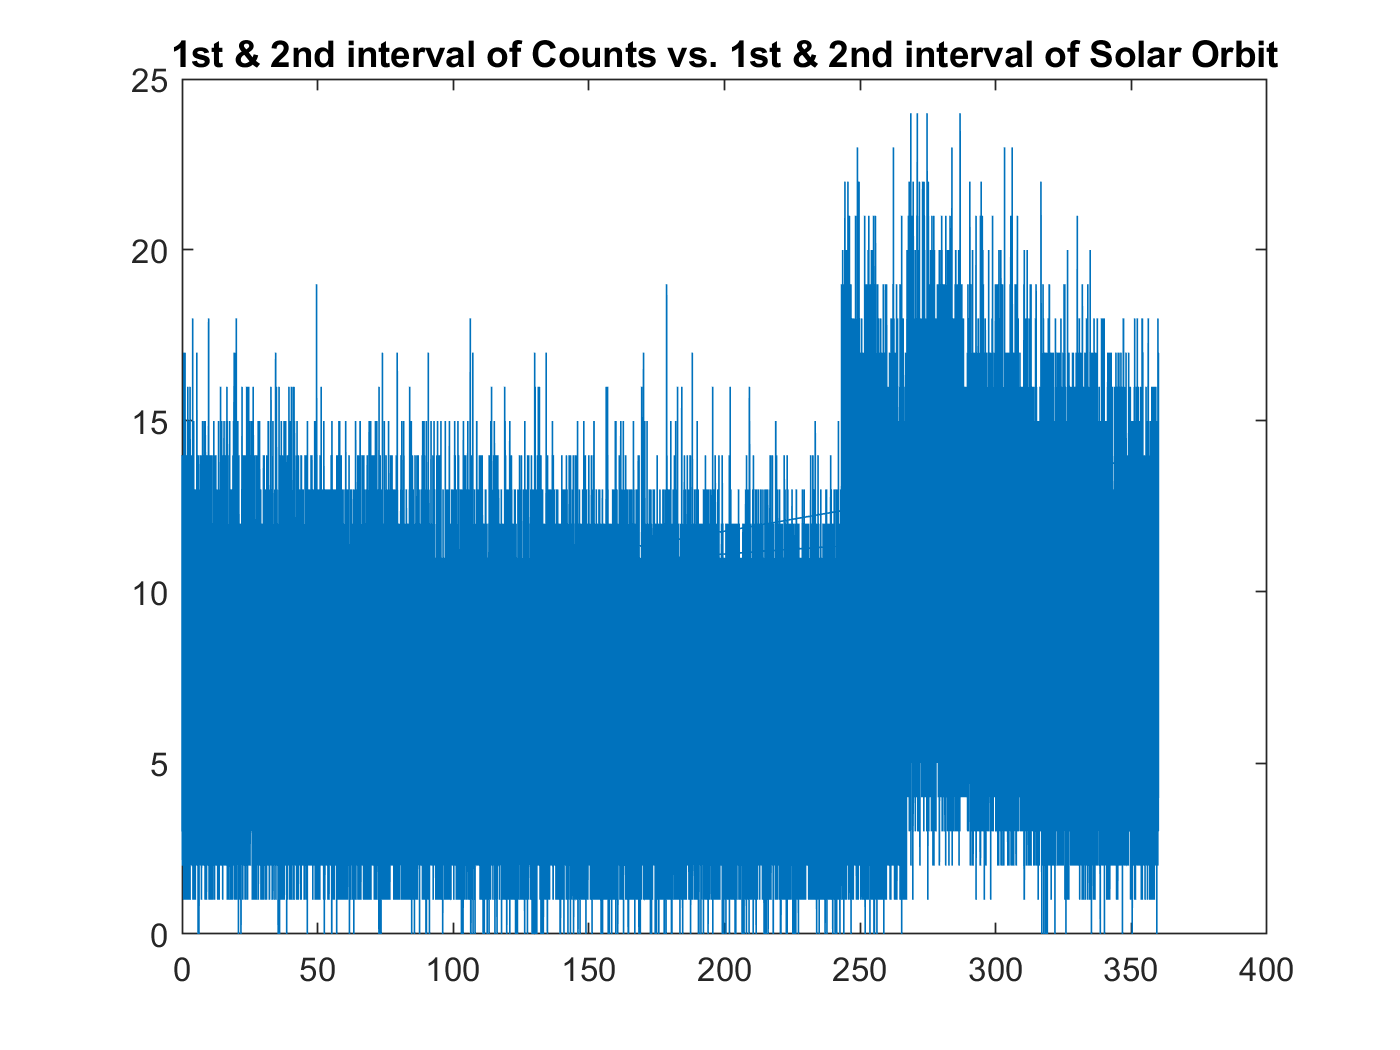

plot(solar2,counts2)
title('1st & 2nd interval of Counts vs. 1st & 2nd interval of Solar Orbit')

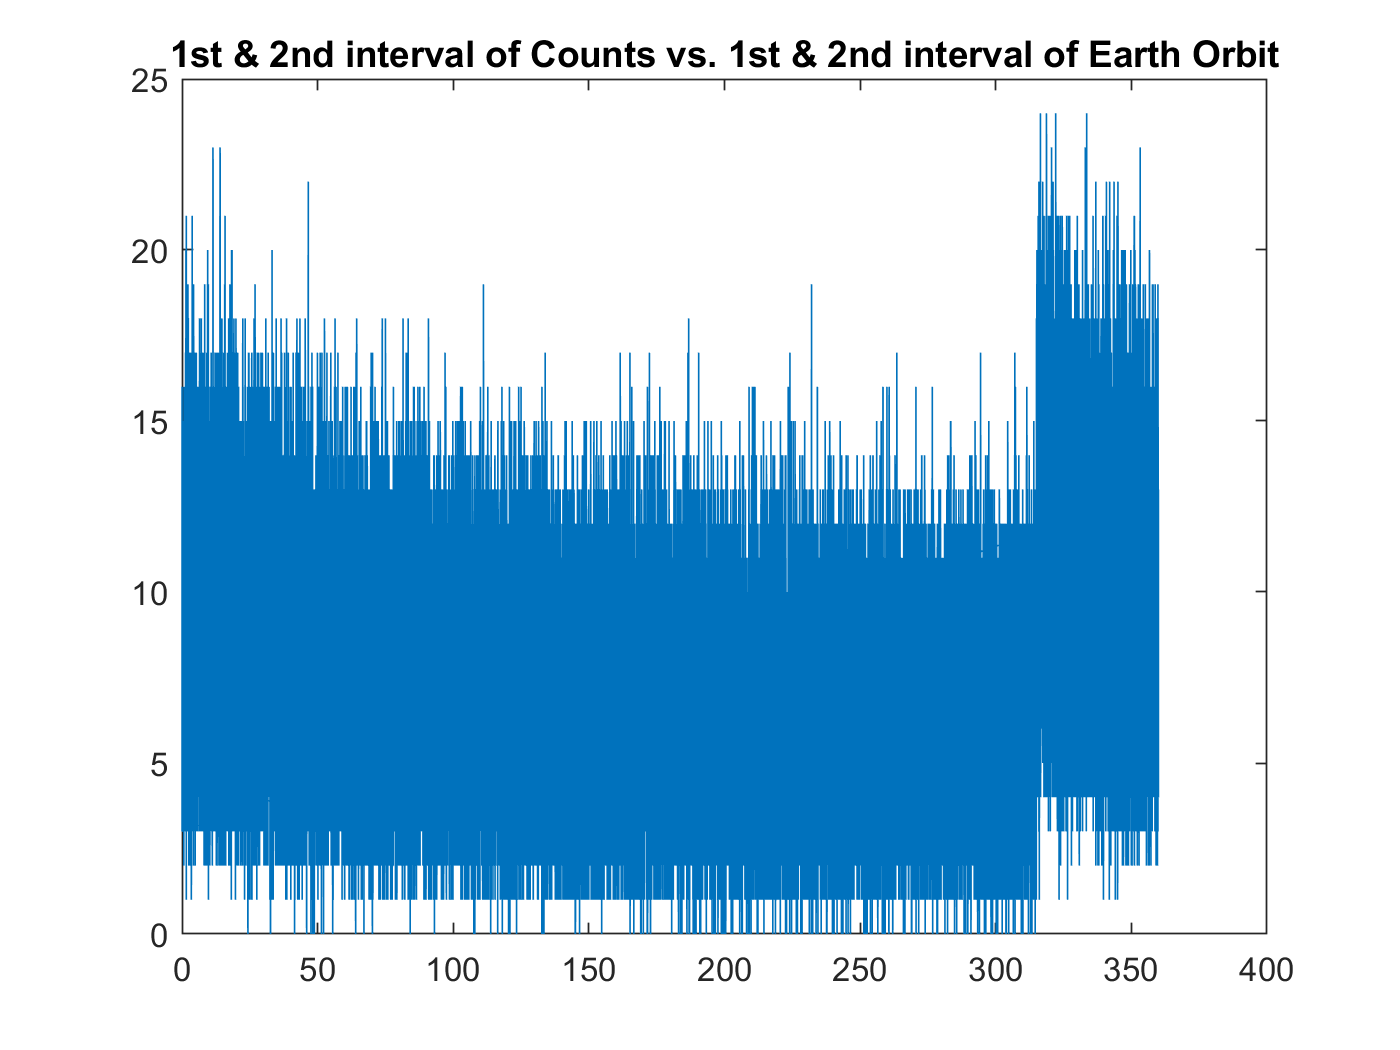

plot(earth2,counts2)
title('1st & 2nd interval of Counts vs. 1st & 2nd interval of Earth Orbit')

No patterns in the solar or earth orbit, like I thought theere would be, will just focus on the counts vs. gps time. 

## Average of the dataset

When you take the 54000 data point intervals and you take the length of the vector of mydata you get that there are 480 intervals. Meaning you will have to sum up 480 intervals and take their average. When taking a look at the data, it is clear that the first reading do not correspond to when the actual orbiting cycle begins. It actually begins around 405000, therefor the first interval of time is from point 40500 to 45000+54000, 54000 being a one cyle orbit. There are only 480 intervals but one of the first bit of the interval is not starting at the begining orbit so we have 479 intervals. 

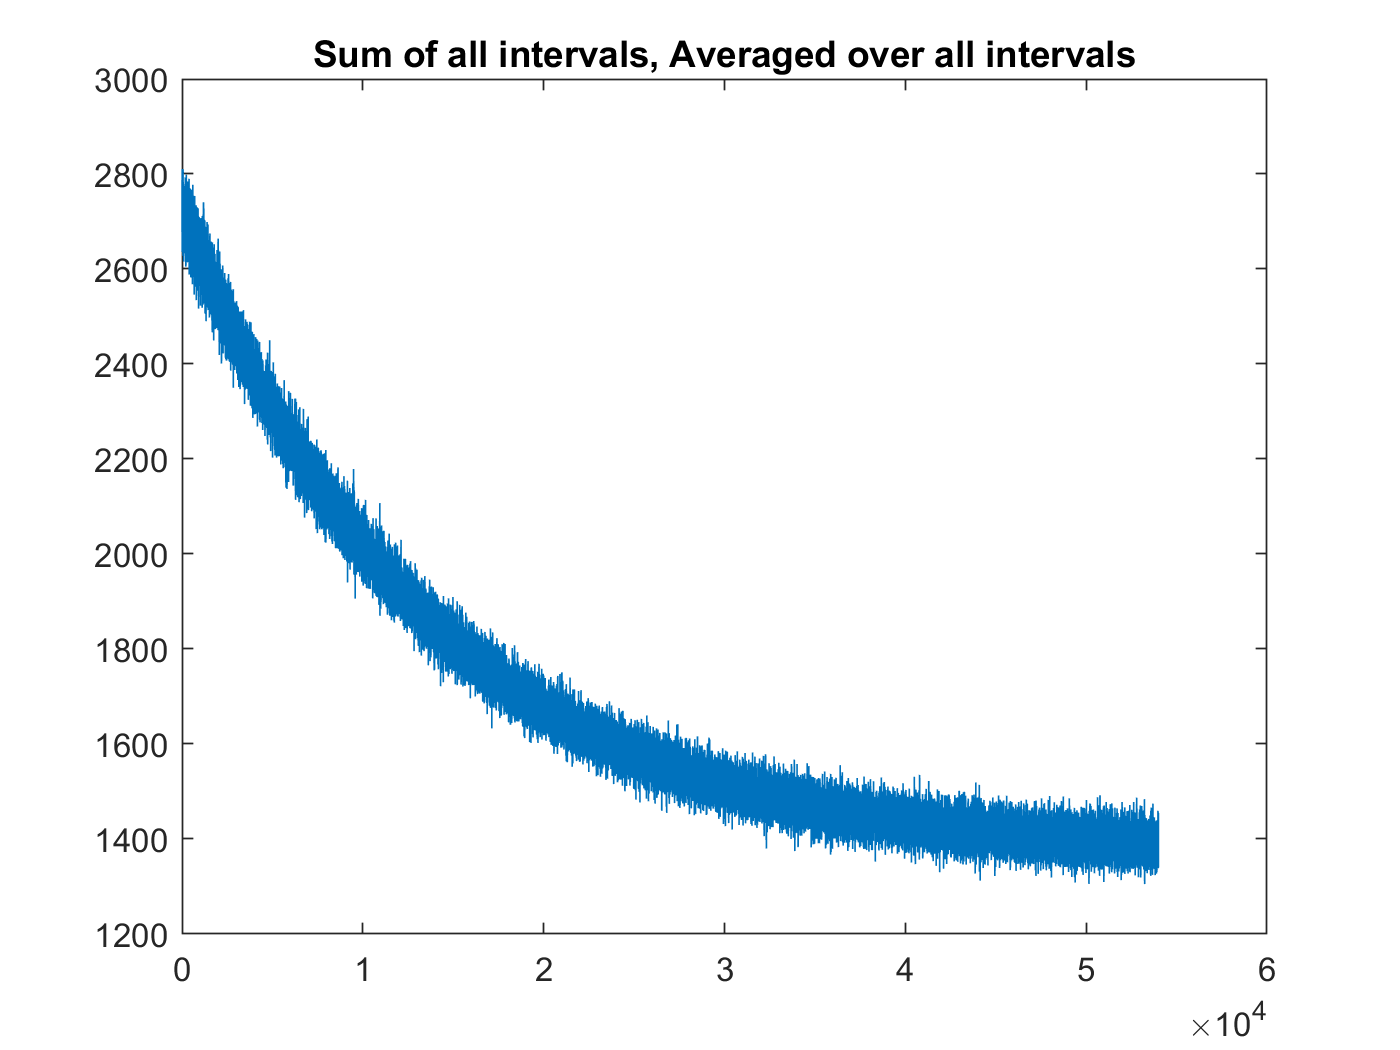

sum=mydata(40500:40500+54000*1-1,4);
    for k=1:length(mydata(:,1))/54000-2
        interval = mydata(1+40500+54000*k:40500+54000*(k+1),4);
        sum= interval+sum;
    end
avgdata=sum/(length(mydata(:,1))/54000-478);
plot(avgdata)
title('Sum of all intervals, Averaged over all intervals')

Through exploring my data, and the relations the metadata had to one another I was able to find and build a background pdf, of an exponential distirbution as shown in the last plot, once we found a pattern in the Counts vs. GPS Time, and a periodic decay we were able to average all the data to encompass all the data. 

**2) The background is not consistent across the dataset. Find and describe as accurately as you can how the background changes. **

It is very clear from the first 3 plots, that the background is not consistent across the datasets, while the plots between counts vs. gps time and counts vs. solar phase were similar, the counts vs. earth phase had a significant amount of data missing which I commented earlier to be a possible source of "signal free" data, because the Earth is blocking the satellite from getting gamma rays, which is scientist like to do with their telescope readings. In order from them to get signal-free data, the will close the telescope dome and take pictures to test the light senseitivity of the telescope. Here the earth is acting as a blockage for signal free data, the only thing that is a problem is earth can emmit gamma rays, by nuclear explosing, lighting and less dramatic activity of radioactivity decay.  So while we found the shape of the distribution and a good possiblilty of signal free data, we need to find which signals are signal contaminations. 

**3) Create a model for the background that includes time dependence, and explicitly compare your model to the data. How good is your model of the background?**

*In order to build a model of the background I would want to make a histogram of the background data on log plot, and from previous part of this lab, find a way to show that they distribution has a time dependance, and the noise created. Below is a code of the model for the background. *

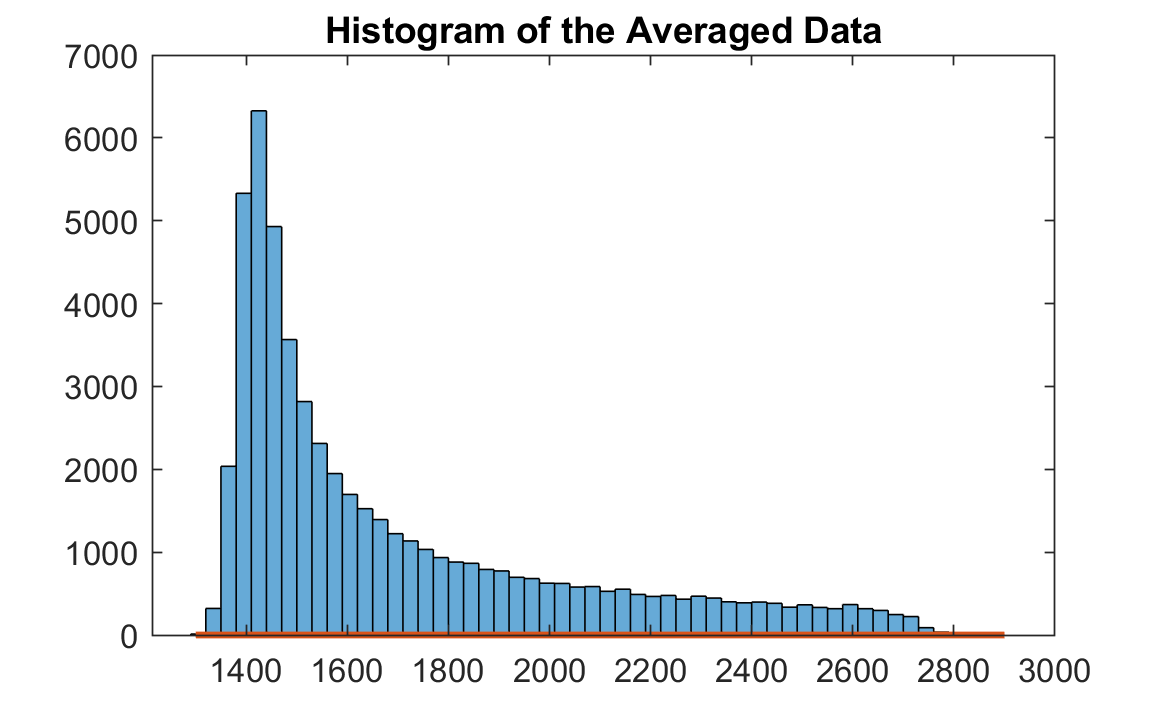

histogram(avgdata);
hold on
title('Histogram of the Averaged Data')
x=avgdata;
pd=fitdist(x,"Exponential");
x_values= 1300:200:3000;
y = pdf(pd,x_values);
plot(x_values,y,'LineWidth',2);
hold off

% cant seem to get the  right, any suggestions?


**4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times?**

*To find the "5-sigma" threhold for a 100 millisecond GRB at different time, I would take the average of the counts of the entired data set, then use an exponential distribution to set the time interval in that 100 millisecond, and get the expected probability distribution for the full run of a 90 minute orbit, then take 5 sigma which is 1 in 3.5 million chance. and find the detection of threshold. *

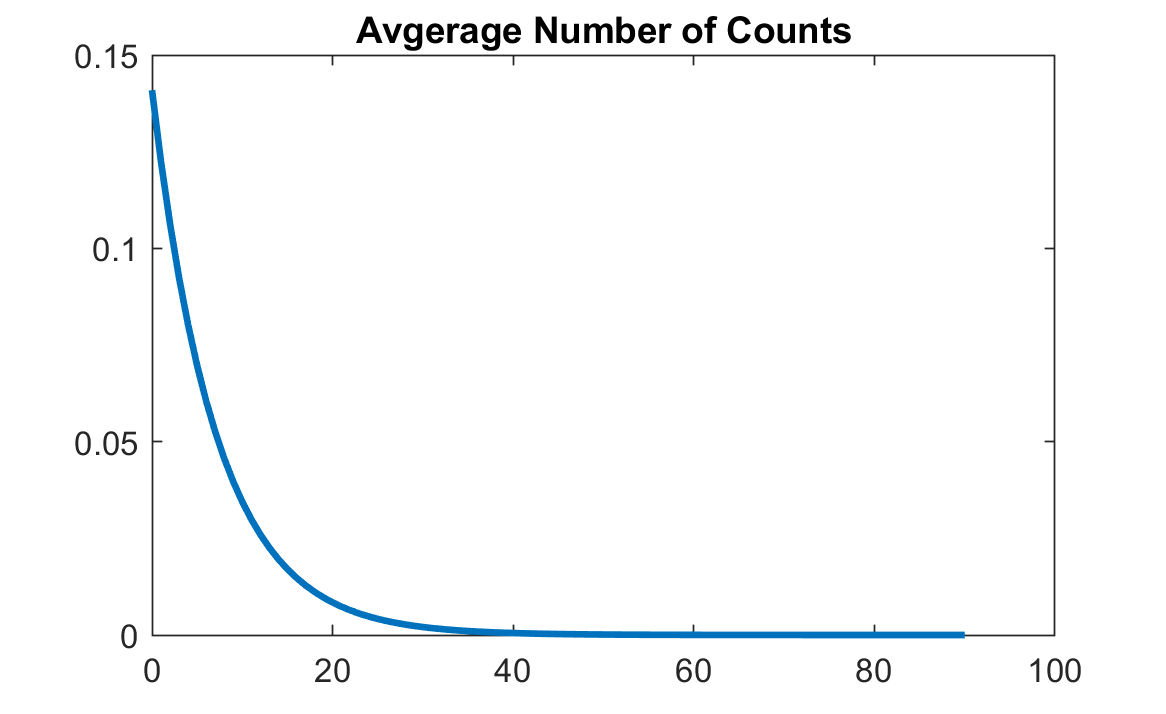

%pdf for counts for all data sets 
x=0:90;
y = mydata(:,4);
avgBackground=mean(y);
exponential = makedist("Exponential","mu",avgBackground);
plot(x,pdf(exponential,x),"LineWidth",2)
title('Avgerage Number of Counts')

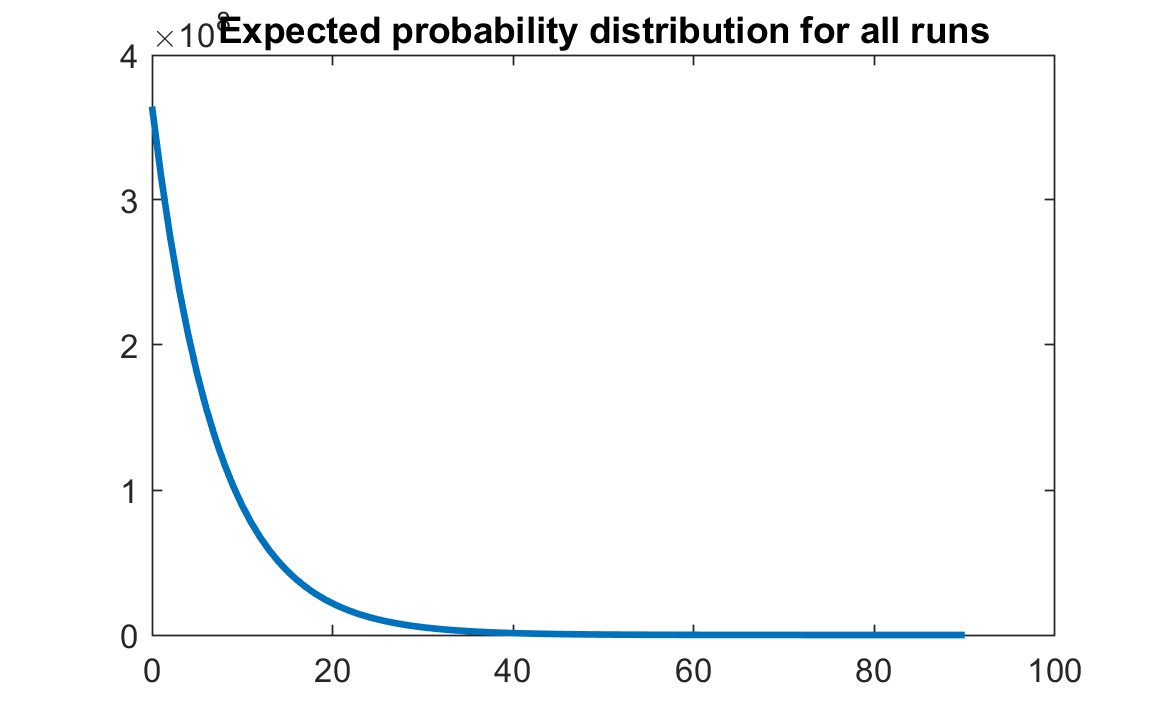


%expected probibility for all all orbit: 
totnummili=(5.4e6)*479;
fullrunexpect=pdf(exponential,x)*totnummili;
plot(x,fullrunexpect,"LineWidth",2)
title('Expected probability distribution for all runs')

prob5sigma=1/3.5e6;
detection=icdf(exponential,1-prob5sigma/totnummili)

detection = 260.7323

(1-cdf(exponential,avgBackground))*totnummili

ans = 9.5156e+08

From this we get we would need to detect a 260.73 counts to have a '5-sigma' threshold for a 100 milisecond GRB at different times, and the probabilty of that hapening is 9.515e8. 

**Optional: while this is simulated data, it is based on a real effect seen by low Earth orbit satellites. Can you identify the cause of the variable background and propose a physical model?**

I have mentioned previously in the lab report, the cause of the vaiable background is when earth is blocking out the gamma ray burst due to the satelite being in low orbit of the earth. Or when there are solar flares from the sun and it hits the detector. A physical model would be to use the time that earch is blocking the statelite as signal free data, then average the other backgrounds to get a true set of data. 

## Problem 2

In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be looking for different signals. One of you will be looking for the faintest stars, while the other will be looking for a transient (something like a super novae that only appears in one image). Flip a coin to determine which of you is pursuing which question.

**1) Dowload the data from **`images.h5`**. This is a stack of 10 square images, each 200 pixels on a side.**

*Below is the code to download the images.h5*

% downloading images.h5 into lab report
h5disp("images.h5");

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


image1=h5read("images.h5",'/image1');
images=h5read("images.h5",'/imagestack');



**2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().**

*Below is code exploring the data thru plots. *

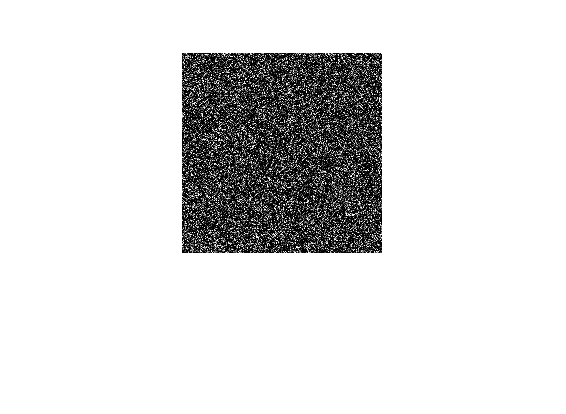

imshow(image1)

Cool but no pattern

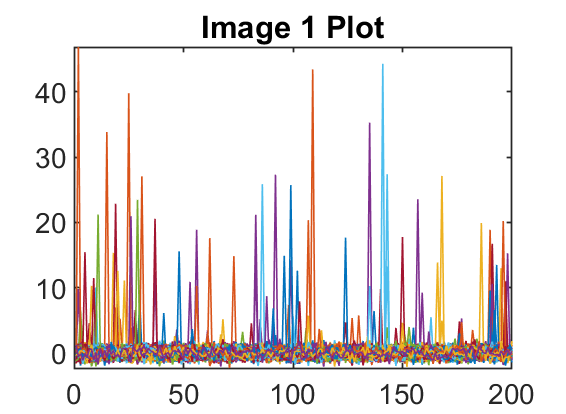

plot(image1)
title('Image 1 Plot')

Hard to read what is going on, there are a lot of colors and lines, there could be a pattern just cannot see it

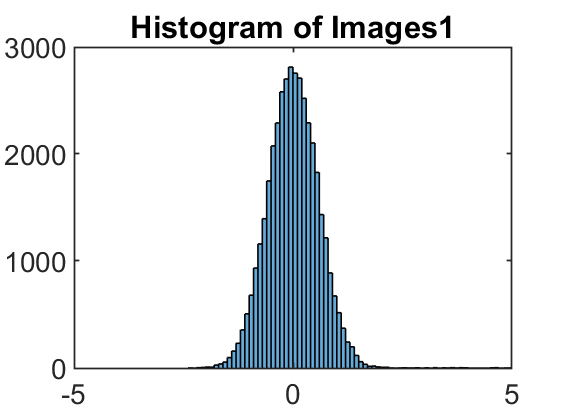

histogram(image1);
title('Histogram of Images1')
xlim([-5,5])

Very intersting to see that it appears to be a guassian distibuition centered at zero, wonder what the log scale looks like.

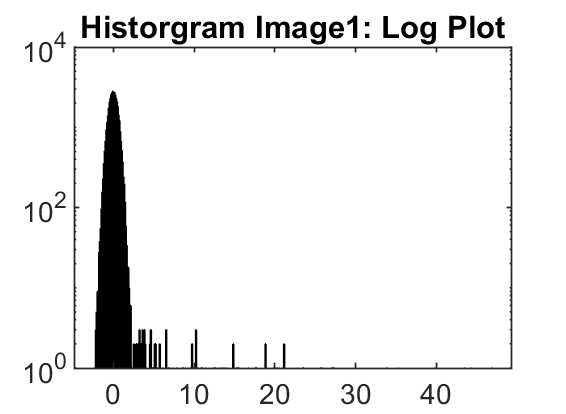

histogram(image1)
set(gca,"YScale",'log')
title('Historgram Image1: Log Plot')

Still guassina for the most part, bu there seem to be a couple of outliers in this image 1. Want to see all the images put together, in other words the 10 stack of images and see wha that distribution looks like. Lastly even though there were no emerging patterns for the imshow command and plot command, I want to see if there are any patterns once we stack all the images. 

a=imtile(images);

No patterns, as to be expected but just had to check 

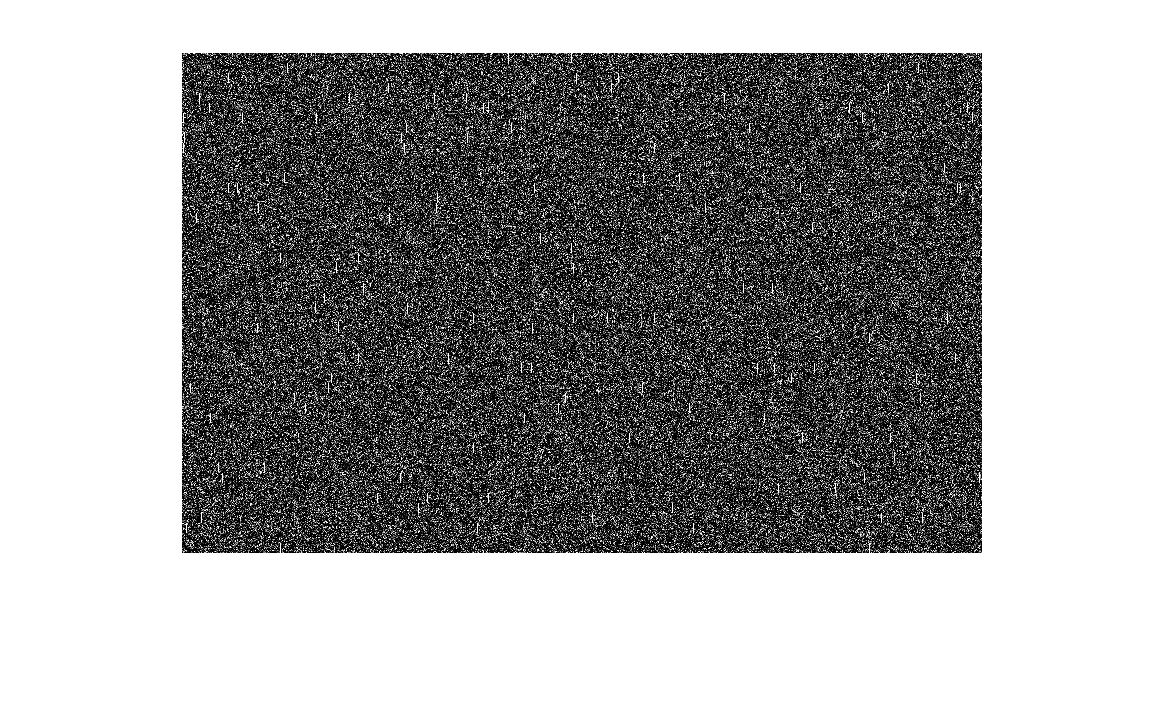

imshow(a)

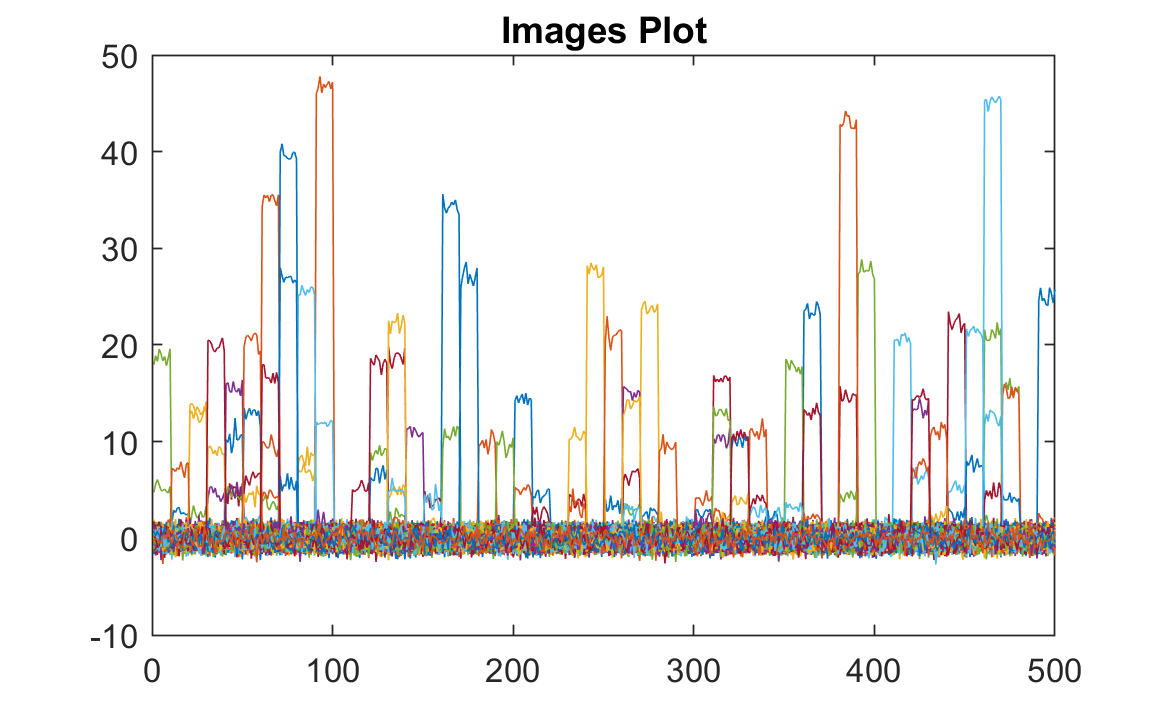

plot(a)
title('Images Plot')

Again really cool graph but no patterns to me that I can see. 

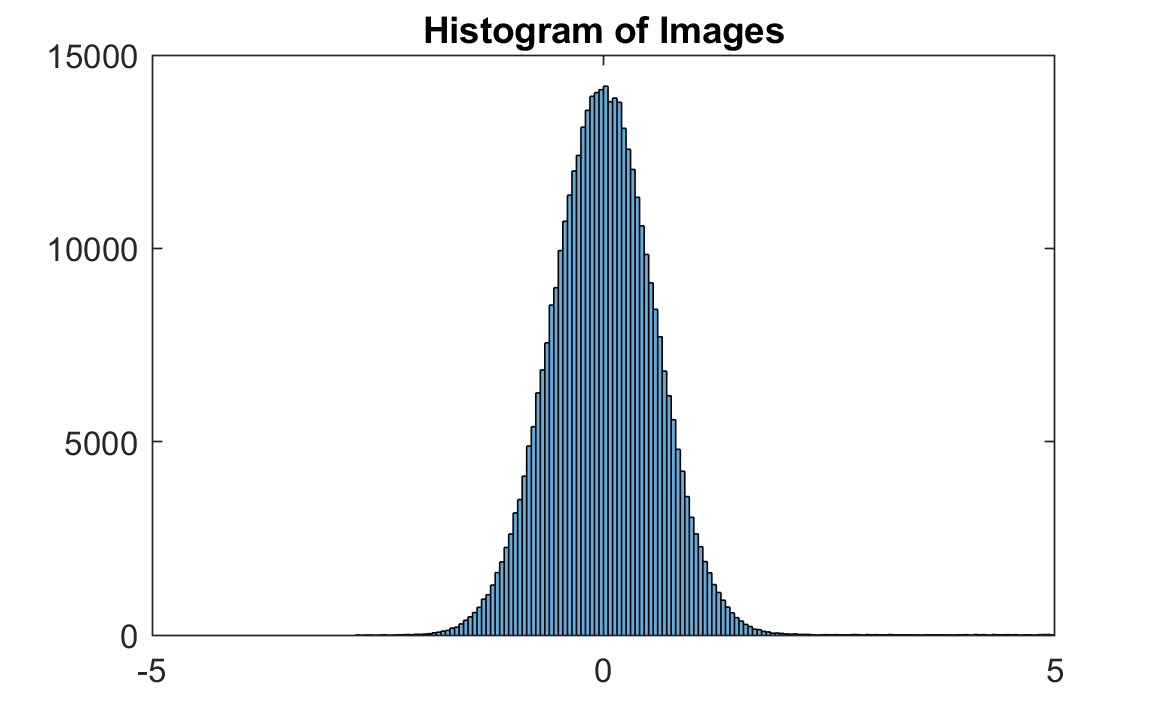

histogram(images);
title('Histogram of Images')
xlim([-5,5])

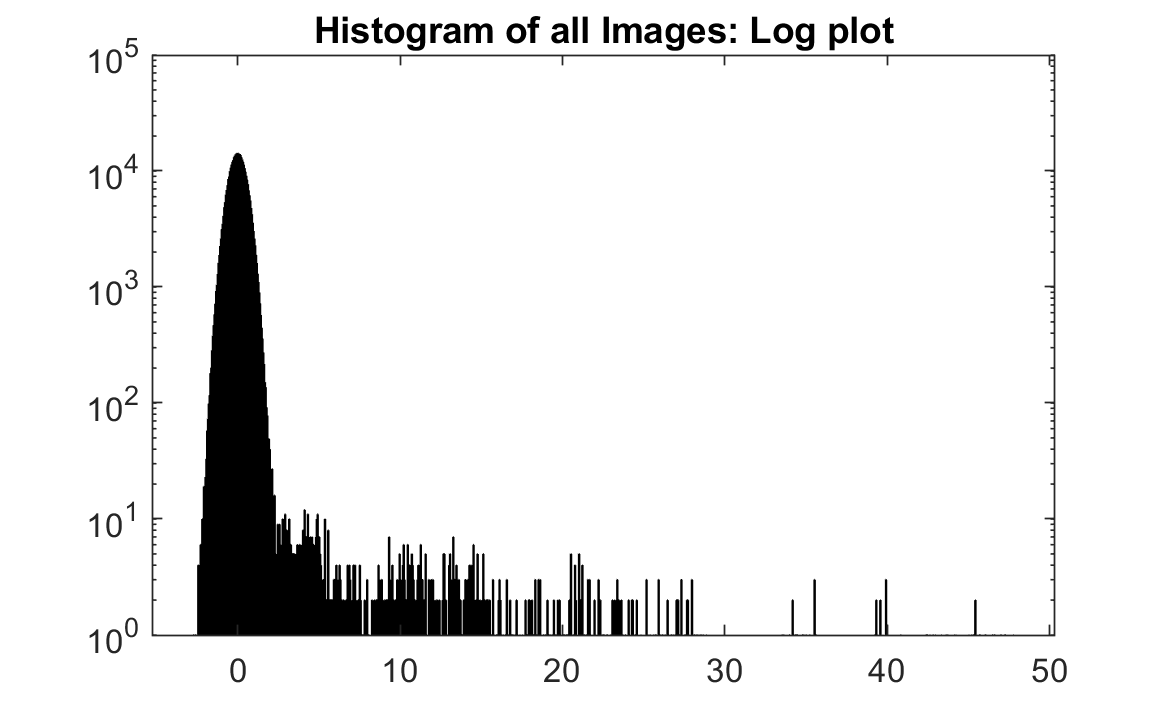

histogram(images)
set(gca,"YScale",'log')
title('Histogram of all Images: Log plot')

The stack of all 10 images seem to still have the same Gaussian background distribution centered at zero, but still more outliers, from the other 9 images, stacked on top of the first image. Even though there is a significant tail, I am looking for the faintist stars, so I really do not need to focus on the tail of the distribution. 

**3) Using your background distribution, hunt for your signal (either faint stars, or a transient). Describe what you find.**

*Below is code for my background distribution and hunt for my signal*

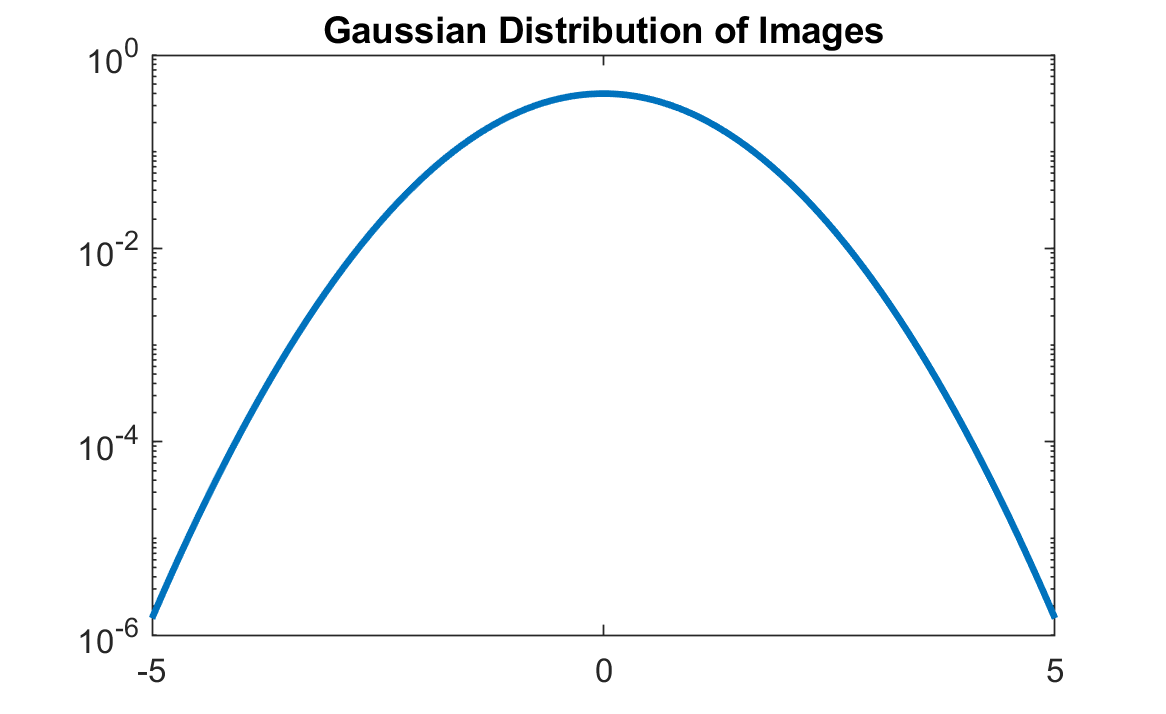

x=linspace(-5,5,100);
gauss = makedist("Normal",'mu',0,'sigma',1);
dist=pdf(gauss,x);
plot(x,dist,"LineWidth",2);
set(gca,"YScale",'log');
title('Gaussian Distribution of Images')

From here, I have my background distribution, to find my faintest starts I would want to find the the stars that were closest to the mean. Therefore, what is the probability of the background prodcuing a signal with less than 0.05 luminosity from a star? 

probability= 1-cdf(gauss,0.05)

probability = 0.4801

sigma=icdf('Normal', 1-probability,0,1)

sigma = 0.0500

From this I can see that the probabililty is pretty high in this distribution which makes sense seeing as I wan anything less than 1 with a sigma of 0.05. 

**4) You and your lab partner had different pdf(), but were using the *****same***** data. Explore why this is**

Since we were looking for different things, our statistcial questions were different, our mathematial interpretations of our statistical question were different and with that, w diverged from each other. Even while we used the same data, if we are looking for different things in the data, we will have differnet results and different pdfs. Since I was looking for the faintest star, I did not care about the tale end of the data that increased in luminosity, I cared about the data that centered around the mean of 0 in the distribution, which is why I chose a Gaussian distribution, while Kuan chose another distribution, because he was interested in finding a supernova, which would be very very bright, so we would want to look at the tail end of that data that increased in luminosity. That is how we ended up with two different distribution. 